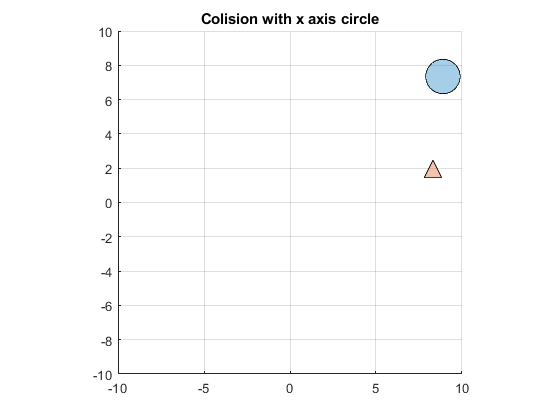

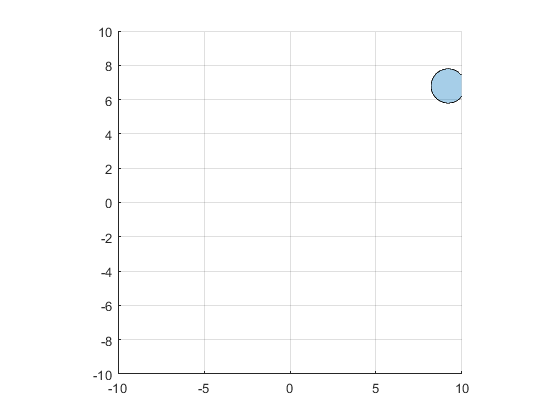

close all
c = circle;
a = polyshape(circle.xdata,circle.ydata);
B = polyshape(triangle.xdata,triangle.ydata);
x = [1 0];
y = [0 1];
trans = zeros(3,2);
random = randi([-10,10],8,1);
ac = [random(1), random(2)];
b = [random(3),random(4)];
acb = [random(5),random(6)];
bc = [random(7),random(8)];
for i = linspace(0,3,50)
    v =   ac*i;
    vb = acb*i;
    f = translate(a, v+b);
    f2 = translate(B,vb+bc);
    % agregar velocidad y un punto de inicio aleatorio
    % detectar colisiones para poligonos
    for j =1:3
        trans(j,:) = [dot(x,f2.Vertices(j,:)), dot(y,f2.Vertices(j,:))];
    end
    p1min = min(trans);
    p1max = max(trans);
    if p1min(1,1) < -10 || p1max(1,1) > 10
        title('Collision with x axis triangle')
        break
    elseif p1min(1,2) < -10 || p1max(1,2) > 10
        title('Colision with y axis triangle')
        break
    end
    [cx,cy] = centroid(f);
    if cx+c.r >= 10 || cx-c.r <= -10
        title('Colision with x axis circle')
        break
    elseif cy+c.r > 10 || cy-c.r <-10
        title('Colision with y axis circle')
        break
    end
    renderer([f,f2])
end